# Section 2

Plot Taylor Series of different degrees of $f(x)=\ln|sin(x+\pi/2)|$

fs = cell(1, 6);

fs{1} = @(x) -x.^2./2;
fs{2} = @(x) fs{1}(x) - x.^4./12;
fs{3} = @(x) fs{2}(x) - x.^6./45;
fs{4} = @(x) fs{3}(x) - 17.*x.^8./2520;
fs{5} = @(x) fs{4}(x) - 31.*x.^10./14175;
fs{6} = @(x) fs{5}(x) - 691.*x.^12./935550;
%fs{7} = @(x) fs{6}(x) - 10922.*x.^14./42567525;

ref = @(x) log(abs(sin(x + pi/2)));

colors = zeros(6, 3);
colors(1:6, :) = [
    [255, 131, 123] / 255;
    [160, 231, 103] / 255;
    [116, 203, 241] / 255;
    [201, 141, 233] / 255;
    [255, 169, 123] / 255;
    [253, 244, 152] / 255
];

Draw  graph

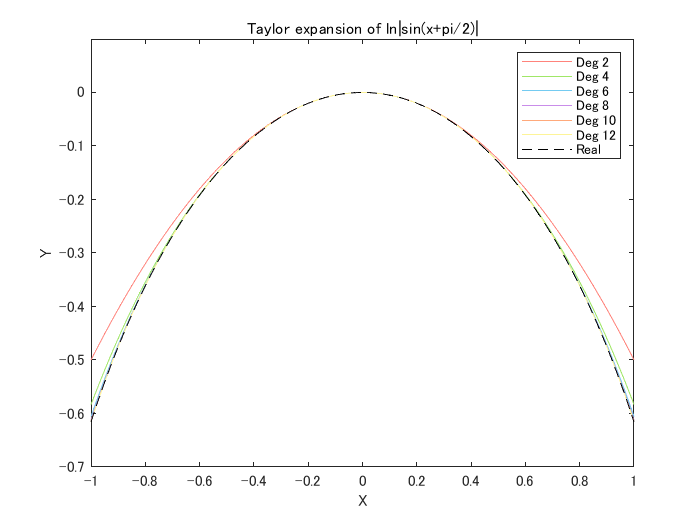

fig = figure(1);
xs = -1:0.01:1;
for i = 1 : 6
    ys = fs{i}(xs);
    plot(xs, ys, "Color", colors(i, :), 'DisplayName', "Deg " + (2 * i));
    if i == 1
        hold on
    end
end

ref_ys = ref(xs);
plot(xs, ref_ys, "Color", [0, 0, 0], "LineStyle", "--", "DisplayName", "Real");

title("Taylor expansion of ln|sin(x+pi/2)|")
xlim([-1, 1])
ylim([-0.7,0.1])
xlabel("X")
ylabel("Y")
legend()
hold off
saveas(gcf, "taylor-graph.png")

Draw error

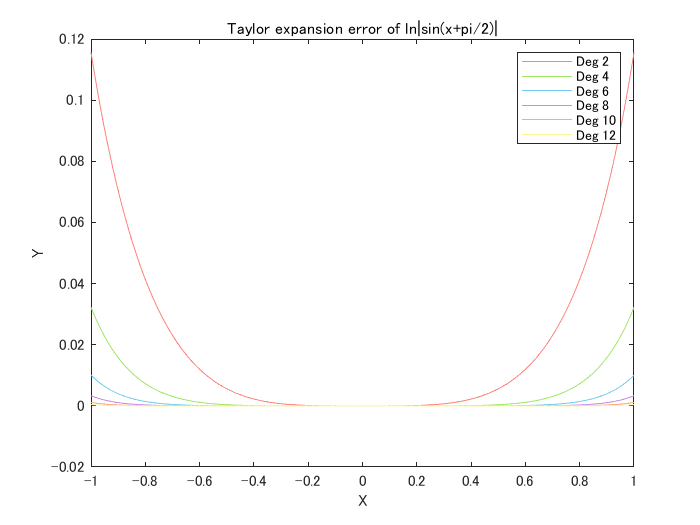

fig = figure(2);
for i = 1 : 6
    ys = fs{i}(xs);
    plot(xs, (ys - ref_ys), "Color", colors(i, :), 'DisplayName', "Deg " + 2 * i);
    if i == 1
        hold on
    end
end

title("Taylor expansion error of ln|sin(x+pi/2)|")
xlim([-1, 1])
xlabel("X")
ylabel("Y")
legend()
hold off
saveas(gcf, "taylor-error.png")

Calculate Integral

% estimate error
xs(189)

ans =    0.880000000000000


err = fs{5}(xs) - ref_ys

err =    0.001137934230812   0.000997763129684   0.000873990568355   0.000764788401343   0.000668524200832   0.000583740843080   0.000509138217603   0.000443556832102   0.000385963111930   0.000335436215469   0.000291156206671   0.000252393443439   0.000218499055948   0.000188896402586   0.000163073403169   0.000140575659793   0.000121000285039   0.000103990365690   0.000089229997539   0.000076439833508   0.000065373093220   0.000055811987437   0.000047564515512   0.000040461598209   0.000034354512037   0.000029112594627   0.000024621193720   0.000020779835068   0.000017500587007   0.000014706601644   0.000012330814623   0.000010314787169   0.000008607675787   0.000007165316372   0.000005949410845   0.000004926805590   0.000004068852035   0.000003350840684   0.000002751500768   0.000002252558478   0.000001838347438   0.000001495465733   0.000001212474364   0.000000979632540   0.000000788665685   0.000000632562458   0.000000505397469   0.000000402176736   0.000000318703220   0.000000251

err(189)

ans =      2.184990559482847e-04


Test for other degrees

c = 5 * pi / 18;
step = 0.0001;
ixss = -c:step:c;

ref_int = sum(-ref(ixss) * step);

disp("Ref integral:")

Ref integral:


disp(ref_int)

   0.241426492157909



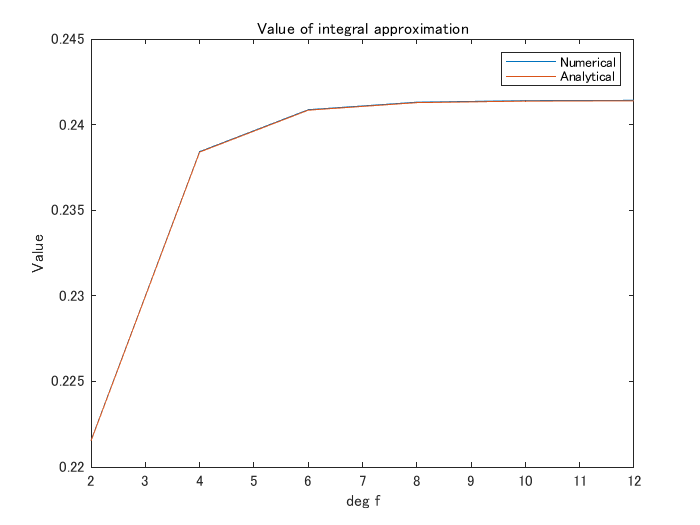


fsi = cell(1, 6);

fsi{1} = @(x) -x.^3./6;
fsi{2} = @(x) fsi{1}(x) - x.^5./60;
fsi{3} = @(x) fsi{2}(x) - x.^7./315;
fsi{4} = @(x) fsi{3}(x) - 17.*x.^9./(2520*9);
fsi{5} = @(x) fsi{4}(x) - 31.*x.^11./(14175*11);
fsi{6} = @(x) fsi{5}(x) - 691.*x.^13./(935550*13);
%fs{7} = @(x) fs{6}(x) - 10922.*x.^14./42567525;

% use numerical method
vals_num = zeros(1, 6);
errs_num = zeros(1, 6);
vals_ana = zeros(1, 6);
errs_ana = zeros(1, 6);
for i = 1 : 6
    vals_num(i) = sum(-fs{i}(ixss) * step);
    errs_num(i) = vals_num(i) - ref_int;
    
    vals_ana(i) = -fsi{i}(c) + fsi{i}(-c);
    errs_ana(i) = vals_ana(i) - ref_int;
end

fig = figure(3);
plot(2 * (1 : 6), vals_num);
hold on
plot(2 * (1 : 6), vals_ana);
title("Value of integral approximation")
xlabel("deg f")
ylabel("Value")
legend("Numerical", "Analytical")
hold off
saveas(gcf, "taylor-integral-value.png")

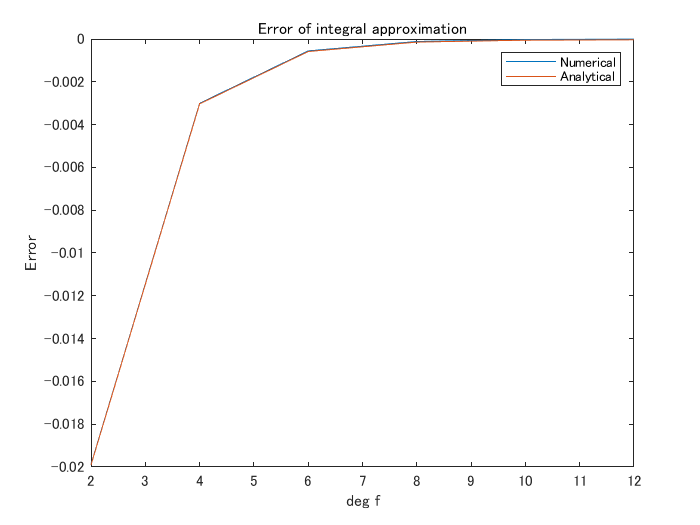


fig = figure(4);
plot(2 * (1 : 6), errs_num);
hold on
plot(2 * (1 : 6), errs_ana);
title("Error of integral approximation")
xlabel("deg f")
ylabel("Error")
legend("Numerical", "Analytical")
hold off
saveas(gcf, "taylor-integral-error.png")

convert result to table

res = [vals_num; errs_num; vals_ana; errs_ana]';
tb = array2table(res, "VariableNames", ...
    ["Value (Numeric)", "Error (Numeric)", "Value (Analytical)", "Error (Analytical)"], ...
    "RowNames", ["Deg 2", "Deg 4", "Deg 6", "Deg 8", "Deg 10", "Deg 12"])

tb = 6×4 table
               Value (Numeric)        Error (Numeric)       Value (Analytical)     Error (Analytical)  
              _________________    _____________________    __________________    _____________________

    Deg 2     0.221550978320438      -0.0198755138374717    0.221524038925324       -0.0199024532325848
    Deg 4     0.238424417933728     -0.00300207422418164    0.238394059214865      -0.00303243294304412
    Deg 6     0.240872208553729    -0.000554283604180028     0.24084115543027      -0.00058533672763969
    Deg 8     0.241312378754541    -0.000114113403367894    0.241281165093353     -0.000145327064556111
    Deg 10    0.241401296952582    -2.51952053271776e-05    0.241370043657112     -5.64485007969184e-05
    Deg 12    0.241420649687486    -5.84247042290098e-06     0.24138938619796     -3.71059599493517e-05


# Section 3

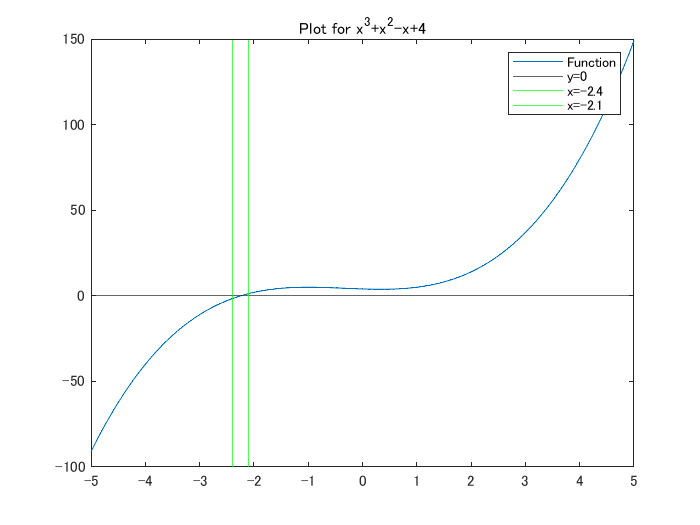

g = @(x) x.^3 + x.^2 - x + 4;

xs = -5:0.01:5;
ys = g(xs);

fig = figure(5);
plot(xs, ys);
title("Plot for x^3+x^2-x+4")
yline(0);
xline([-2.4, -2.1], "Color", "green")
legend("Function", "y=0", "x=-2.4", "x=-2.1")
saveas(gcf, "function.png")


data = cell(1, 6);

bisection method: Observe the graph, I will choose $[-2.4,-2.1]$ as the initial interval.

disp("[Bisection Method]")

[Bisection Method]



N = 1000;
tol = 1e-9;

ind = 0;
a = -2.4;
b = -2.1;

res = 0;

data{1} = [];
data{2} = [];

while ind < N
    c = (a + b) / 2;
    data{1} = [data{1} ind];
    data{2} = [data{2} c];
    
    if abs(g(c)) < tol || abs(a - b) < tol
        res = c;
        break;
    end
    ind = ind + 1;
    if g(a) * g(c) < 0
        b = c;
    else
        a = c;
    end
end

Solution = x1;
FunctionValue = g(x1);
Iterations = ind;

result = table(Solution, FunctionValue, Iterations);
result

result = 1×3 table
        Solution             FunctionValue        Iterations
    _________________    _____________________    __________

    -2.24189656303448    -1.77635683940025e-15        29    


Fixed point method: use the same initial value $x_0=-2.4$. (convergence proved in the report)

disp("[Fixed Point Method]")

[Fixed Point Method]



x1 = -2.4;
x0 = 9999999;

tol = 1e-9;
ind = 0;

phi = @(x) (x - 4) ./ x .^ 2 - 1;

data{3} = [];
data{4} = [];

while abs(x0 - x1) > tol
    x0 = x1;
    x1 = phi(x1);
    ind = ind + 1;
    
    data{3} = [data{3} ind];
    data{4} = [data{4} x1];
end

Solution = x1;
FunctionValue = g(x1);
Iterations = ind;

result = table(Solution, FunctionValue, Iterations);
result

result = 1×3 table
        Solution            FunctionValue        Iterations
    _________________    ____________________    __________

    -2.24189656256146    4.53838211456059e-09       205    


Newton's Method, use the same initial value $x_0=-2.4$.

disp("[Newton's Method]")

[Newton's Method]



x1 = -2.4;
x0 = 9999999;

tol = 1e-9;
ind = 0;

phi = @(x) x-(x.^3+x.^2-x+4)./(3*x.^2+2.*x-1);

data{5} = [];
data{6} = [];

while abs(x0 - x1) > tol
    x0 = x1;
    x1 = phi(x1);
    ind = ind + 1;
    
    data{5} = [data{5} ind];
    data{6} = [data{6} x1];
end

Solution = x1;
FunctionValue = g(x1);
Iterations = ind;

result = table(Solution, FunctionValue, Iterations);
result

result = 1×3 table
        Solution             FunctionValue        Iterations
    _________________    _____________________    __________

    -2.24189656303448    -1.77635683940025e-15        5     


Plot the result

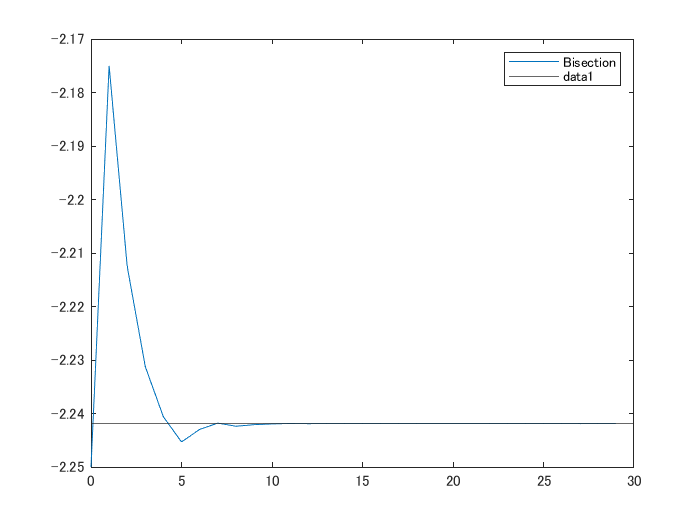

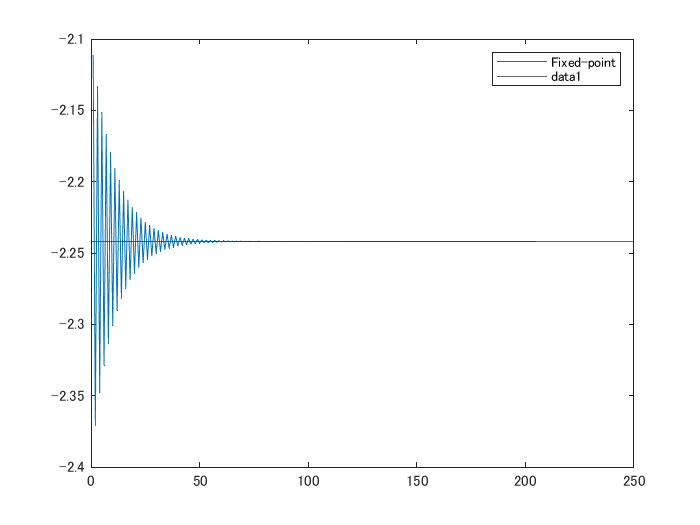

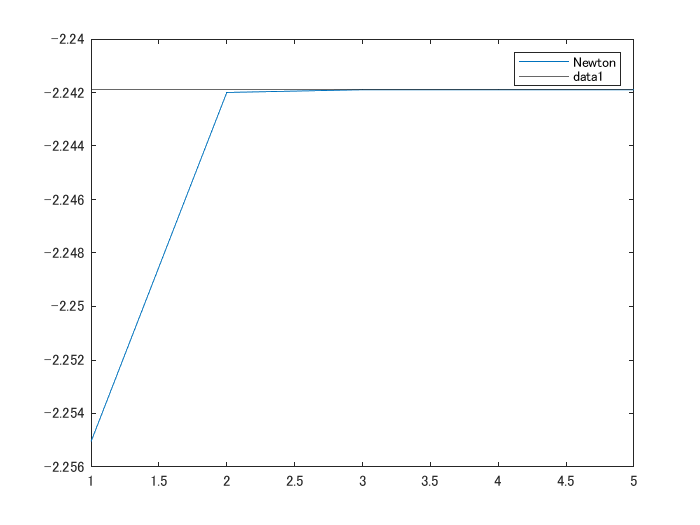

leds = ["Bisection", "Fixed-point", "Newton"];
for i = 1 : 3
    fig = figure(5 + i);
    plot(data{2 * i - 1}, data{2 * i});
    legend(leds(i))
    yline(-2.2418965630344796)
    saveas(gcf, leds(i) + ".png")
end